%% HW-4 BSS-Not In LiveScript: Arani-810100511
clear; clc; close all;
%% Generate S <Source Signal>:
fs = 20; %Hz
ts = 1/fs;

K = 5;

T_rec = K-ts;
t= 0:ts:T_rec;

c = [0.2,0.4, 0.6,-0.1,-0.3];
d = [0.1 0.3 -0.2  0.5 -0.3];

C = repmat(c,fs,1);
D = repmat(d,fs,1);

s1 = (C(:))'.*sin(2*pi*t);
s2 = (D(:))'.*sin(4*pi*t);

S = [s1;s2];

%% Generate X:
A = [0.8,-0.6; 0.6 , 0.8];
X = A*S;


%% Plot the Source (S) & Observation Signal(X):

figure()
subplot(2,1,1)
plot(t,S)
grid on
legend("Source Signal-1","Source Signal-2")
title("Source Signal")
ylabel("Amplitude")

subplot(2,1,2)
plot(t,X)
grid on
legend("Observ Signal-1","Observ Signal-2")
title("Observ Signal")
xlabel("Time [s]")


%% Data Whitening & BSS SOlve -Part B


RX = X*X';
[U_X , Lambda_X] = eig(RX);
% Method 1:
% W_whit  = chol(inv(RX));
% Z = W_whit'*X;
% Method 2:
Whitener =(Lambda_X^(-1/2))*U_X.';
% Z=X;
Whitener =1;
Z = Whitener*X;

RZ = Z*Z';

[U_Z , Lambda_Z] = eig(RZ);

k=1;
RZ_k1 = Z(:, (k-1)*fs+1:(k)*fs  )*Z(:,(k-1)*fs+1:(k)*fs  )';
k=2;
RZ_k2 = Z( :,(k-1)*fs+1:(k)*fs  )*Z(:,(k-1)*fs+1:(k)*fs  )';

[Q,Lambda_Z_K] = eig(inv(RZ_k2)*RZ_k1);
B = Q';

S_Amp = S/norm(S,"fro");
[~ , B_Hat_Chosen ] = Perm_AMP_Disamb(B,inv(Whitener)*Z,S_Amp);
S_hat = B_Hat_Chosen*inv(Whitener)*Z;
S_hat_perm_AMp = S_hat/norm(S_hat,'fro');  % Normalization
Error = (norm(S_hat_perm_AMp-S_Amp,'fro'))^2/(norm(S_Amp,'fro'))^2 ; 

disp("Error = "+Error);

Error = 1.8876e-31


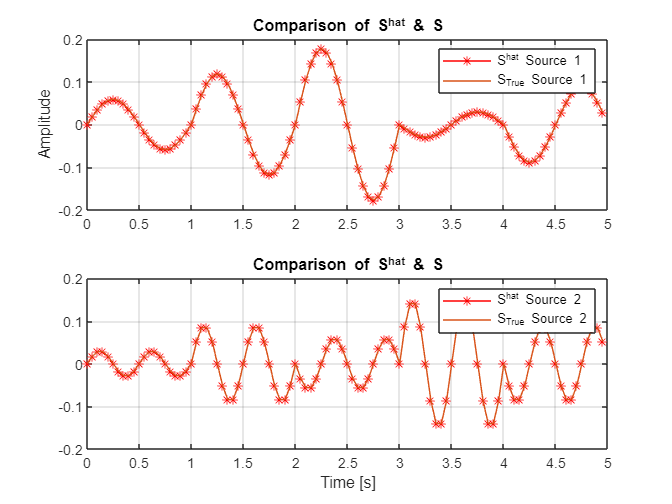


figure()
subplot(2,1,1)
plot(t,S_hat_perm_AMp(1,:),'r-*')
hold on
plot(t,S_Amp(1,:))
title("Comparison of S^{hat} & S")
grid on
ylabel("Amplitude")
legend("S^{hat} Source 1","S_{True} Source 1" )

subplot(2,1,2)
plot(t,S_hat_perm_AMp(2,:),'r-*')
hold on
plot(t,S_Amp(2,:))
title("Comparison of S^{hat} & S")
grid on
legend("S^{hat} Source 2","S_{True} Source 2" )
xlabel("Time [s]")

Window_Num = K;
B_Hat = Diag_Joint_Func(Z,fs,Window_Num,Num_iter,S_Amp);
[Errors_B , B_Hat_Chosen ] = Perm_AMP_Disamb(B_Hat,inv(Whitener)*Z,S_Amp);
S_hat = B_Hat_Chosen*inv(Whitener)*Z;   % Estimation of S
S_hat_perm_AMp = S_hat/norm(S_hat,'fro');  % Normalization
Error = (norm(S_hat_perm_AMp-S_Amp,'fro'))^2/(norm(S_Amp,'fro'))^2 ; % Calc the Error

disp("Error = "+Error);

Error = 2.0075e-32


BSS_Opt = BSS_SOlver(X,Window_Num,fs,S_Amp);
disp(BSS_Opt);

             Error: 2.0075e-32
          Errors_B: [4.0000 2.0075e-32 2.0000 2.0000]
      B_Hat_Chosen: [2×2 double]
          Whitener: 1
                 Z: [2×100 double]
                 X: [2×100 double]
                RX: [2×2 double]
          Lambda_X: [2×2 double]
               U_X: [2×2 double]
             S_Amp: [2×100 double]
    S_hat_perm_AMp: [2×100 double]



% Calculate Error For Different Window Numbers:
cntr=1;
NUm_Iters =100;
BSS_Opt_K = cell(NUm_Iters,length(2:K));
Error_Wind_k = zeros(1,length(2:K));


for k=2:K
    for i=1:NUm_Iters
        BSS_Opt_K{cntr,i} = BSS_SOlver(X,k,fs,S_Amp);
        Error_Wind_k(cntr)= Error_Wind_k(cntr)+BSS_Opt_K{cntr,i}.Error;
    end
    Error_Wind_k(cntr) = Error_Wind_k(cntr)/NUm_Iters;
    cntr=cntr+1;
end


## Plot Error VS Window Number:

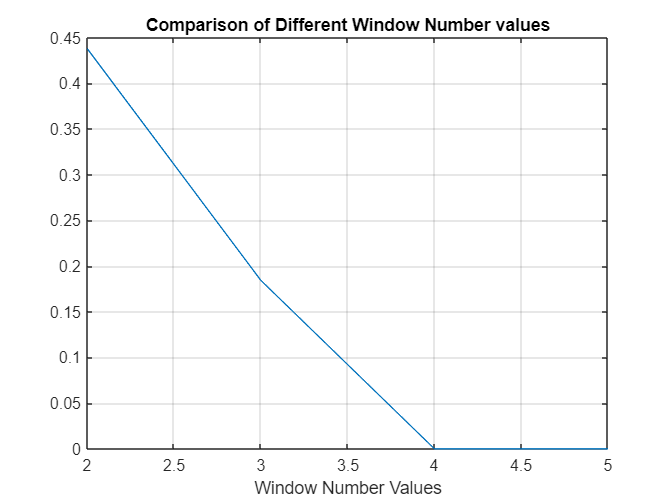

figure()
plot(2:K, Error_Wind_k )
grid on
title("Comparison of Different Window Number values")
xlabel("Window Number Values")


SNR = 20;
BSS_Opt_Noisy =BSS_Noisy(X,SNR,Window_Num,fs,S_Amp);



% Solve for Different SNR values:
SNR_vec = [5,10,15,20];
NUm_Iters = 100;
BSS_Sols  =cell(length(SNR_vec),NUm_Iters);
Window_Num = K;
Error_SNR = zeros(1,length(SNR_vec));

for i=1:length(SNR_vec)
    SNR = SNR_vec(i);
    for iter =1:NUm_Iters
        BSS_Opt_Noisy =BSS_Noisy(X,SNR,Window_Num,fs,S_Amp);
        BSS_Sols{i,iter} = BSS_Opt_Noisy;
        Error_SNR(i) = BSS_Opt_Noisy.Error+Error_SNR(i);
    end
    Error_SNR(i) = Error_SNR(i)/NUm_Iters;

end


## Plot The Result:   Error VS SNR

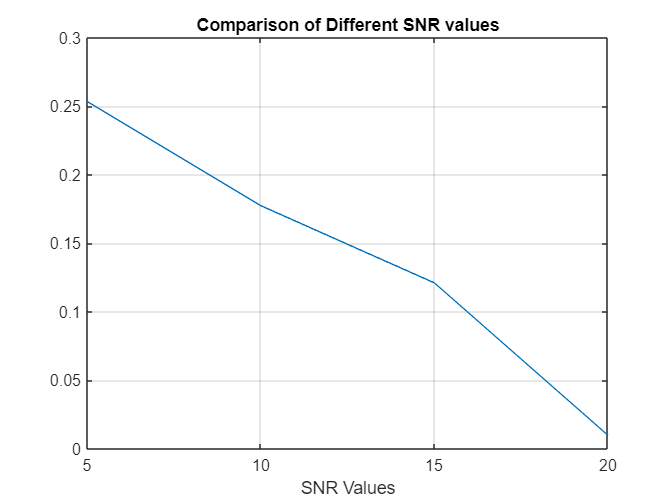

figure()
plot(SNR_vec, Error_SNR )
grid on
title("Comparison of Different SNR values")
xlabel("SNR Values")

## Section 2:

X1_Data = load("hw4-X1.mat");
fs_X1 = 100; %100Hz
ts_X1 = 1/fs_X1;


X1 = X1_Data.X1;
Window_Num = length(X1)/fs_X1;
T_rec_X1 = Window_Num; 
t_x1 = 0:ts_X1:T_rec_X1-ts_X1;
S_Amp = randn(size(X1));
BSS_SOl_X1 = BSS_SOlver(X1,Window_Num,fs_X1,S_Amp);
S_hat_X1 = BSS_SOl_X1.B_Hat_Chosen*X1;

## Plot X1-BSS Solved S-Hat

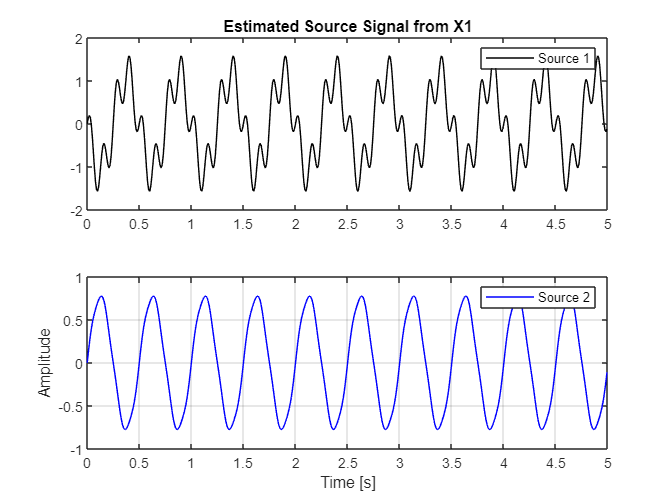


figure()
subplot(2,1,1)
plot(t_x1,S_hat_X1(1,:),'black')
title("Estimated Source Signal from X1")
legend("Source 1")
subplot(2,1,2)
plot(t_x1,S_hat_X1(2,:),'b')
grid on
xlabel("Time [s]")
ylabel("Amplitude")
legend("Source 2")

## Fourier Transform-X1:

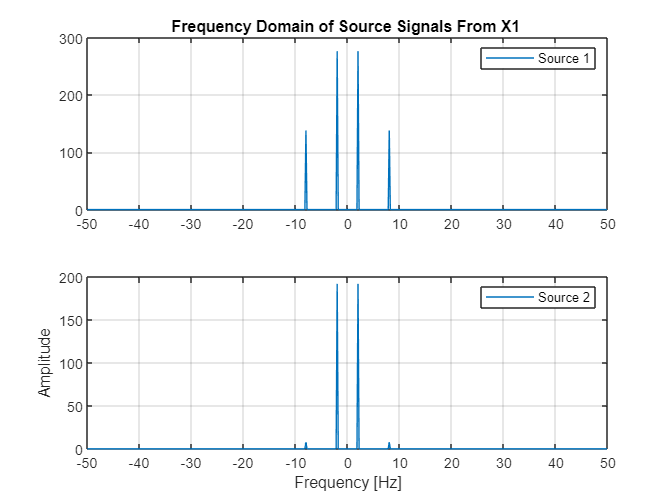

delta_f_X1 = 1/T_rec_X1;
freq_X1 = -fs_X1/2:delta_f_X1:fs_X1/2-delta_f_X1; % Frequency Axis


% Source 1 FFT:
S_hat_X1_F_1 = fftshift(fft(S_hat_X1(1,:)));
% Source 2 FFT:
S_hat_X1_F_2 = fftshift(fft(S_hat_X1(2,:)));

figure()
subplot(2,1,1)
plot(freq_X1,abs(S_hat_X1_F_1))
grid on
title("Frequency Domain of Source Signals From X1 ")
legend("Source 1")
subplot(2,1,2)
plot(freq_X1,abs(S_hat_X1_F_2))
grid on
legend("Source 2")
xlabel("Frequency [Hz]")
ylabel("Amplitude")

## SOlving X1 BSS with 2 Windows

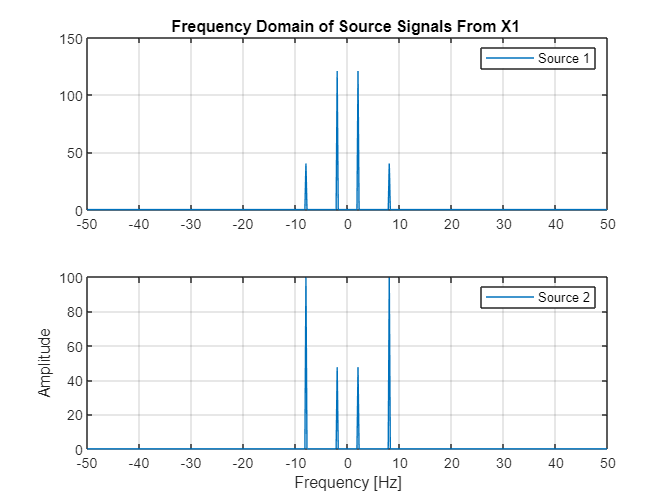

BSS_Opt_SOl_Unique = BSS_Unique_Solver(X1,fs_X1,length(X1)/2);
S_hat_X1_Unique = BSS_Opt_SOl_Unique.B*X1;

% Source 1 FFT:
S_hat_X1_F_1 = fftshift(fft(S_hat_X1_Unique(1,:)));
% Source 2 FFT:
S_hat_X1_F_2 = fftshift(fft(S_hat_X1_Unique(2,:)));

figure()
subplot(2,1,1)
plot(freq_X1,abs(S_hat_X1_F_1))
grid on
title("Frequency Domain of Source Signals From X1 ")
legend("Source 1")
subplot(2,1,2)
plot(freq_X1,abs(S_hat_X1_F_2))
grid on
legend("Source 2")
xlabel("Frequency [Hz]")
ylabel("Amplitude")

## FInd LCM of T1 and T2 for Window Size:

% We have f1 and f2 from FFT above
f1 = 2; % 2Hz
f2 = 8; % 8Hz

T1 = 1/f1;
T2 = 1/f2;

T_window = lcm(1000*T1,1000*T2) ;
T_window = T_window/1000;


We can see that The overall signal period is 0.5 [s] so that in this signal, we can have 10 windows with this size! 

If we take Half of the Total recording Time as our Window, so we have chosen a correct multiply of 0.5 [s] which is 2.5 [s] in which 2 signals must be uncorrelated!

Then the result above is verified.

## SOlving X2 BSS with 2 Windows

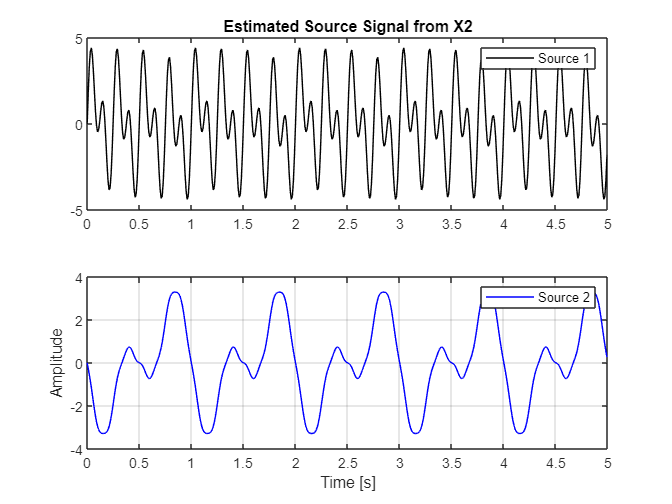

X2_Data = load("hw4-X2.mat");
fs_X2 = 100; %100Hz
ts_X2 = 1/fs_X2;


X2 = X2_Data.X2;
Window_Num = length(X2)/fs_X2;
T_rec_X2 = Window_Num; 
t_x2 = 0:ts_X2:T_rec_X2-ts_X2;
S_Amp = randn(size(X2));
BSS_SOl_X2 = BSS_SOlver(X2,Window_Num,fs_X2,S_Amp);
S_hat_X2 = BSS_SOl_X2.B_Hat_Chosen*X2;

figure()
subplot(2,1,1)
plot(t_x2,S_hat_X2(1,:),'black')
title("Estimated Source Signal from X2")
legend("Source 1")
subplot(2,1,2)
plot(t_x2,S_hat_X2(2,:),'b')
grid on
xlabel("Time [s]")
ylabel("Amplitude")
legend("Source 2")

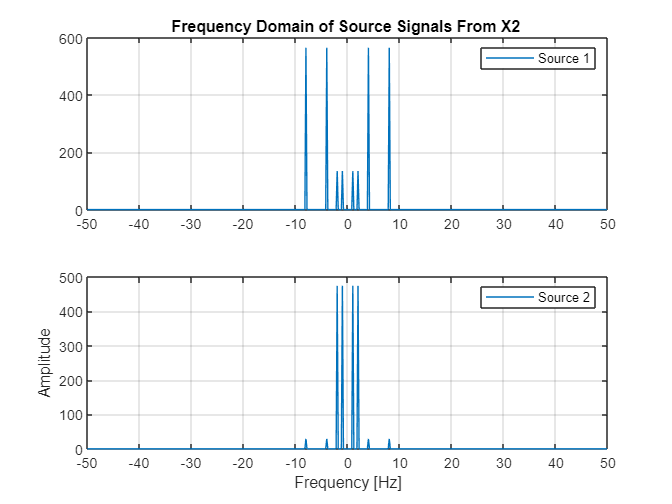


BSS_Opt_SOl_Unique = BSS_Unique_Solver(X2,fs_X2,length(X2)/2);
S_hat_X2_Unique = BSS_Opt_SOl_Unique.B*X2;

delta_f_X2 = 1/T_rec_X2;
freq_X2 = -fs_X2/2:delta_f_X2:fs_X2/2-delta_f_X2; % Frequency Axis
% Source 1 FFT:
S_hat_X2_F_1 = fftshift(fft(S_hat_X2_Unique(1,:)));
% Source 2 FFT:
S_hat_X2_F_2 = fftshift(fft(S_hat_X2_Unique(2,:)));

figure()
subplot(2,1,1)
plot(freq_X2,abs(S_hat_X2_F_1))
grid on
title("Frequency Domain of Source Signals From X2 ")
legend("Source 1")
subplot(2,1,2)
plot(freq_X2,abs(S_hat_X2_F_2))
grid on
legend("Source 2")
xlabel("Frequency [Hz]")
ylabel("Amplitude")

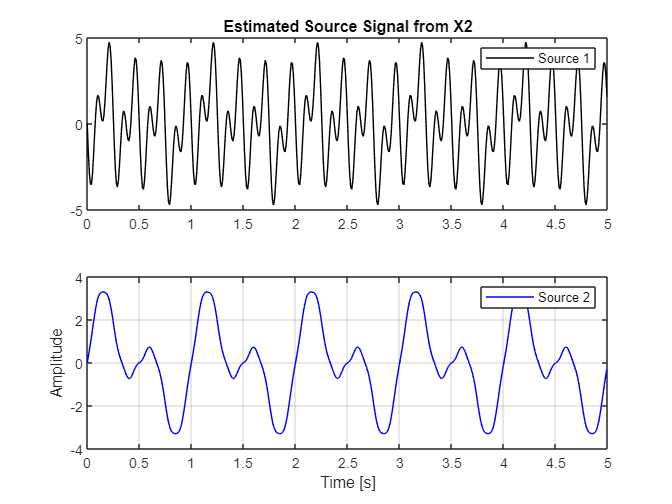

figure()
subplot(2,1,1)
plot(t_x2,S_hat_X2_Unique(1,:),'black')
title("Estimated Source Signal from X2")
legend("Source 1")
subplot(2,1,2)
plot(t_x2,S_hat_X2_Unique(2,:),'b')
grid on
xlabel("Time [s]")
ylabel("Amplitude")
legend("Source 2")

function BSS_Opt = BSS_Unique_Solver(X,fs,Window_Size)


RX = X*X';
[U_X , Lambda_X] = eig(RX);
% Whietning:
Whitener =(Lambda_X^(-1/2))*U_X.';
% Z=X;
Whitener =1;
Z = Whitener*X;

% RZ = Z*Z';
% [U_Z , Lambda_Z] = eig(RZ);
% Window_Size = length(Z);


RZ_k1 = Z( :, 1:floor(Window_Size)  )    *Z(:, 1:floor(Window_Size)  )';
RZ_k2 = Z( :, floor(Window_Size)+1:end  )*Z(:,floor(Window_Size)+1:end  )';

[Q,Lambda_Z_K] = eig(inv(RZ_k2)*RZ_k1);
B = Q.'*Whitener;

BSS_Opt.B = B;
BSS_Opt.Z = Z;
BSS_Opt.X = X;
BSS_Opt.fs = fs;


end






function   BSS_Opt = BSS_SOlver(X,Window_Num,fs,S_Amp)

RX = X*X';
[U_X , Lambda_X] = eig(RX);
% Whietning:
Whitener =(Lambda_X^(-1/2))*U_X.';
% Z=X;
Whitener =1;
Z = Whitener*X;

Num_iter = 100;

B_Hat = Diag_Joint_Func(Z,fs,Window_Num,Num_iter,S_Amp);
[Errors_B , B_Hat_Chosen ] = Perm_AMP_Disamb(B_Hat,inv(Whitener)*Z,S_Amp);
S_hat = B_Hat_Chosen*inv(Whitener)*Z;   % Estimation of S
S_hat_perm_AMp = S_hat/norm(S_hat,'fro');  % Normalization
Error = (norm(S_hat_perm_AMp-S_Amp,'fro'))^2/(norm(S_Amp,'fro'))^2 ; % Calc the Error


BSS_Opt.Error = Error;
BSS_Opt.Errors_B = Errors_B;
BSS_Opt.B_Hat_Chosen = B_Hat_Chosen;
BSS_Opt.Whitener = Whitener;
BSS_Opt.Z=Z;
BSS_Opt.X =X;
BSS_Opt.RX = RX;
BSS_Opt.Lambda_X = Lambda_X;
BSS_Opt.U_X = U_X;
BSS_Opt.S_Amp = S_Amp;
BSS_Opt.S_hat_perm_AMp =S_hat_perm_AMp;


end
function BSS_Opt =BSS_Noisy(X,SNR,Window_Num,fs,S_Amp)

SNR_lin = 10^(SNR/10);
sigma = sqrt( norm(X,"fro")^2/SNR_lin );

W = randn(size(X));
W_normalised = W/norm(W,"fro") ;  
Y  = X + sigma*W_normalised ;

BSS_Opt = BSS_SOlver(Y,Window_Num,fs,S_Amp);

end

function B_Hat = Diag_Joint_Func(Z,fs,Window_Num,Num_iter,S_Amp)

RZ = Z*Z';
B_Hat = orth(rand(size(RZ)));
    for iter = 1:Num_iter
         R_2 = 0;
         R_1 =0;
        for k=1:Window_Num
            RZ_k  = Z(:, (k-1)*fs+1:(k)*fs  )*Z(:,(k-1)*fs+1:(k)*fs  )';
            for j=1:length(B_Hat)
                if (j==1)
                    b_j = B_Hat(j,:)' ;
                    R_2 = R_2 + (RZ_k*b_j)*(RZ_k*b_j)';
        
                else
                    b_j = B_Hat(j,:)' ; % Doubt Here!!!! Choose Columns or Rows of B???
                    R_1 = R_1 + (RZ_k*b_j)*(RZ_k*b_j)';
        
                end
            end
        
        end
    
    [V_R1,Lambda_R1] = eig(R_1);
    [~, ind] = sort(diag(Lambda_R1),'descend');
    V_R1 = V_R1(:, ind);
    b_1 =  V_R1(:,end); % According to lowest eigen Value
    
    % For b_2:
    [V_R2,Lambda_R2] = eig(R_2);
    [~, ind] = sort(diag(Lambda_R2),'descend');
    V_R2 = V_R2(:, ind);
    b_2 =  V_R2(:,end); % According to lowest eigen Value
    % b_2 = ( eye(size(b_2))  - b_1*b_1' )*b_2 ;
    b_2 = b_2 - (b_1'*b_2)*b_2 ;
    b_2 = b_2/norm(b_2,2); % Normalization
    
    B_Hat = [b_1' ; b_2'];
    
    end

end


function [Erroes_B,B_Hat_Chosen]  = Perm_AMP_Disamb(B_Hat,Z,S_Amp) %% Perm_AMP_Disamb
Perm_1 = B_Hat;
Perm_2 = -B_Hat;
Perm_3 = B_Hat([end, 1:end-1],:);
Perm_4 = -B_Hat([end, 1:end-1],:);
Perms = { Perm_1,Perm_2,Perm_3,Perm_4  };
% Estimate S:
S_hat_1 = Perm_1*Z;
S_hat_1_Normalised = S_hat_1/norm(S_hat_1,'fro');
S_hat_2 = Perm_2*Z;
S_hat_2_Normalised = S_hat_2/norm(S_hat_2,'fro');
S_hat_3 = Perm_3*Z;
S_hat_3_Normalised = S_hat_3/norm(S_hat_3,'fro');
S_hat_4 = Perm_4*Z;
S_hat_4_Normalised = S_hat_4/norm(S_hat_4,'fro');
% Calc Error:
Error_1 = (norm((S_hat_1_Normalised)-(S_Amp),'fro'))^2 ; 
Error_2 = (norm((S_hat_2_Normalised)-(S_Amp),'fro'))^2 ; 
Error_3 = (norm((S_hat_3_Normalised)-(S_Amp),'fro'))^2 ; 
Error_4 = (norm((S_hat_4_Normalised)-(S_Amp),'fro'))^2 ; 

Erroes_B = [Error_1,Error_2,Error_3,Error_4];
[ ~, index] = min(Erroes_B);
B_Hat_Chosen = Perms{index};
end
